syms f n w t
f=n*cos(n*w*t)

$$f = n\,\cos\left(n\,t\,w\right)$$

v=[]


v =

     []



for i=1:5
    v=[v subs(subs(f,w,2*10*pi),n,i)]
end

$$v = \cos\left(20\,\pi \,t\right)$$

$$v = \left(\begin{array}{cc} \cos\left(20\,\pi \,t\right) & 2\,\cos\left(40\,\pi \,t\right) \end{array}\right)$$

$$v = \left(\begin{array}{ccc} \cos\left(20\,\pi \,t\right) & 2\,\cos\left(40\,\pi \,t\right) & 3\,\cos\left(60\,\pi \,t\right) \end{array}\right)$$

$$v = \left(\begin{array}{cccc} \cos\left(20\,\pi \,t\right) & 2\,\cos\left(40\,\pi \,t\right) & 3\,\cos\left(60\,\pi \,t\right) & 4\,\cos\left(80\,\pi \,t\right) \end{array}\right)$$

$$v = \left(\begin{array}{ccccc} \cos\left(20\,\pi \,t\right) & 2\,\cos\left(40\,\pi \,t\right) & 3\,\cos\left(60\,\pi \,t\right) & 4\,\cos\left(80\,\pi \,t\right) & 5\,\cos\left(100\,\pi \,t\right) \end{array}\right)$$

clear f n w
g=sum(v)

$$g = \cos\left(20\,\pi \,t\right)+2\,\cos\left(40\,\pi \,t\right)+3\,\cos\left(60\,\pi \,t\right)+4\,\cos\left(80\,\pi \,t\right)+5\,\cos\left(100\,\pi \,t\right)$$

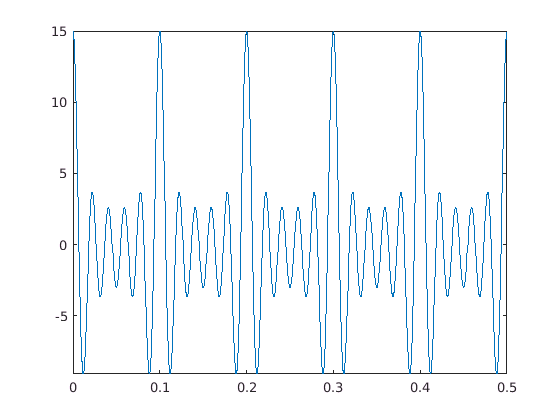

fplot(g,[0,.5])

syms x
gf=fourier(g,t,x)

$$gf = \pi \,\left(\delta (x-20\,\pi )+\delta (x+20\,\pi )\right)+2\,\pi \,\left(\delta (x-40\,\pi )+\delta (x+40\,\pi )\right)+3\,\pi \,\left(\delta (x-60\,\pi )+\delta (x+60\,\pi )\right)+4\,\pi \,\left(\delta (x-80\,\pi )+\delta (x+80\,\pi )\right)+5\,\pi \,\left(\delta (x-100\,\pi )+\delta (x+100\,\pi )\right)$$

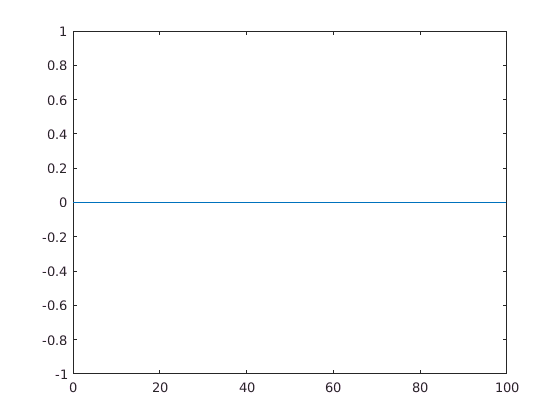

fplot(gf,[0,100])

discrete_domain=0:.005:.495

discrete_domain =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


discrete_range=double(subs(g,t,discrete_domain))

discrete_range =    15.0000    5.5685   -7.7361   -6.1195    2.5000    2.0000   -3.2639   -1.5887    2.5000    0.1397   -3.0000    0.1397    2.5000   -1.5887   -3.2639    2.0000    2.5000   -6.1195   -7.7361    5.5685   15.0000    5.5685   -7.7361   -6.1195    2.5000    2.0000   -3.2639   -1.5887    2.5000    0.1397   -3.0000    0.1397    2.5000   -1.5887   -3.2639    2.0000    2.5000   -6.1195   -7.7361    5.5685   15.0000    5.5685   -7.7361   -6.1195    2.5000    2.0000   -3.2639   -1.5887    2.5000    0.1397


plot(discrete_domain,discrete_range)
discrete_fourier=fftshift(fft(discrete_range))

discrete_fourier =    1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.000

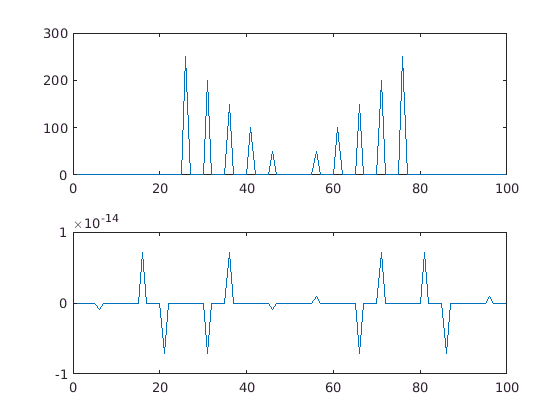

subplot(2,1,1)
plot(1:length(discrete_domain),real(discrete_fourier))
subplot(2,1,2)
plot(1:length(discrete_domain),imag(discrete_fourier))

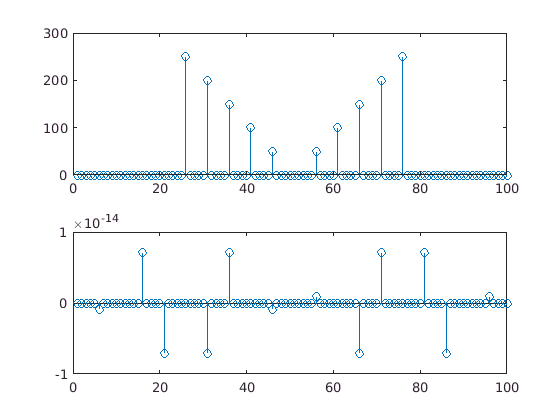

figure
subplot(2,1,1)
stem(1:length(discrete_domain),real(discrete_fourier))
subplot(2,1,2)
stem(1:length(discrete_domain),imag(discrete_fourier))